MATLAB`基础`

•`变量与函数`

•`基本数学运算符号`

•`命令行中常用标点`

•`命令窗口中常用操作和编辑命令`

cd

F:\Users\Ggross\Documents\MATLAB\Github\CourseNotes\Matlab_Notes\matlab_basic



path = cd;
path = strcat(cd, "\test.txt")

path = "F:\Users\Ggross\Documents\MATLAB\Github\CourseNotes\Matlab_Notes\matlab_basic\test.txt"

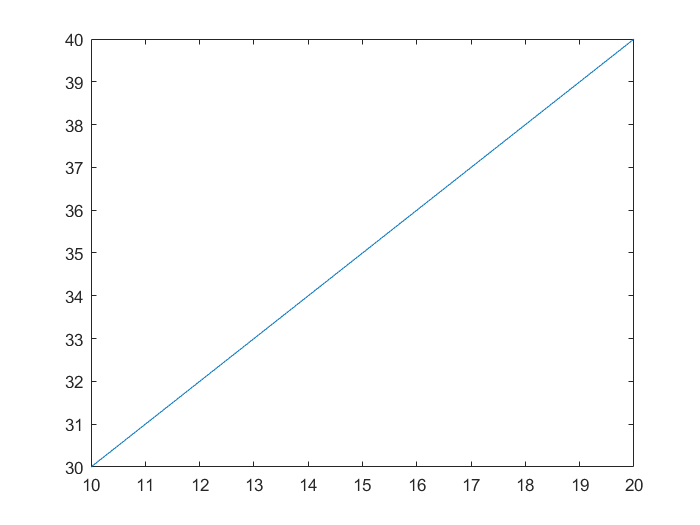

diary(path);

a=10:20;b=30:40;plot(a,b);

diary on
x=a.*b

x =    300   341   384   429   476   525   576   629   684   741   800


diary off

who a


您的变量为:

a  



whos a

  Name      Size            Bytes  Class     Attributes

  a         1x11               88  double              



A=0.25;
B=0.35;
format short
A

A = 0.2500

format long
A

A =    0.250000000000000


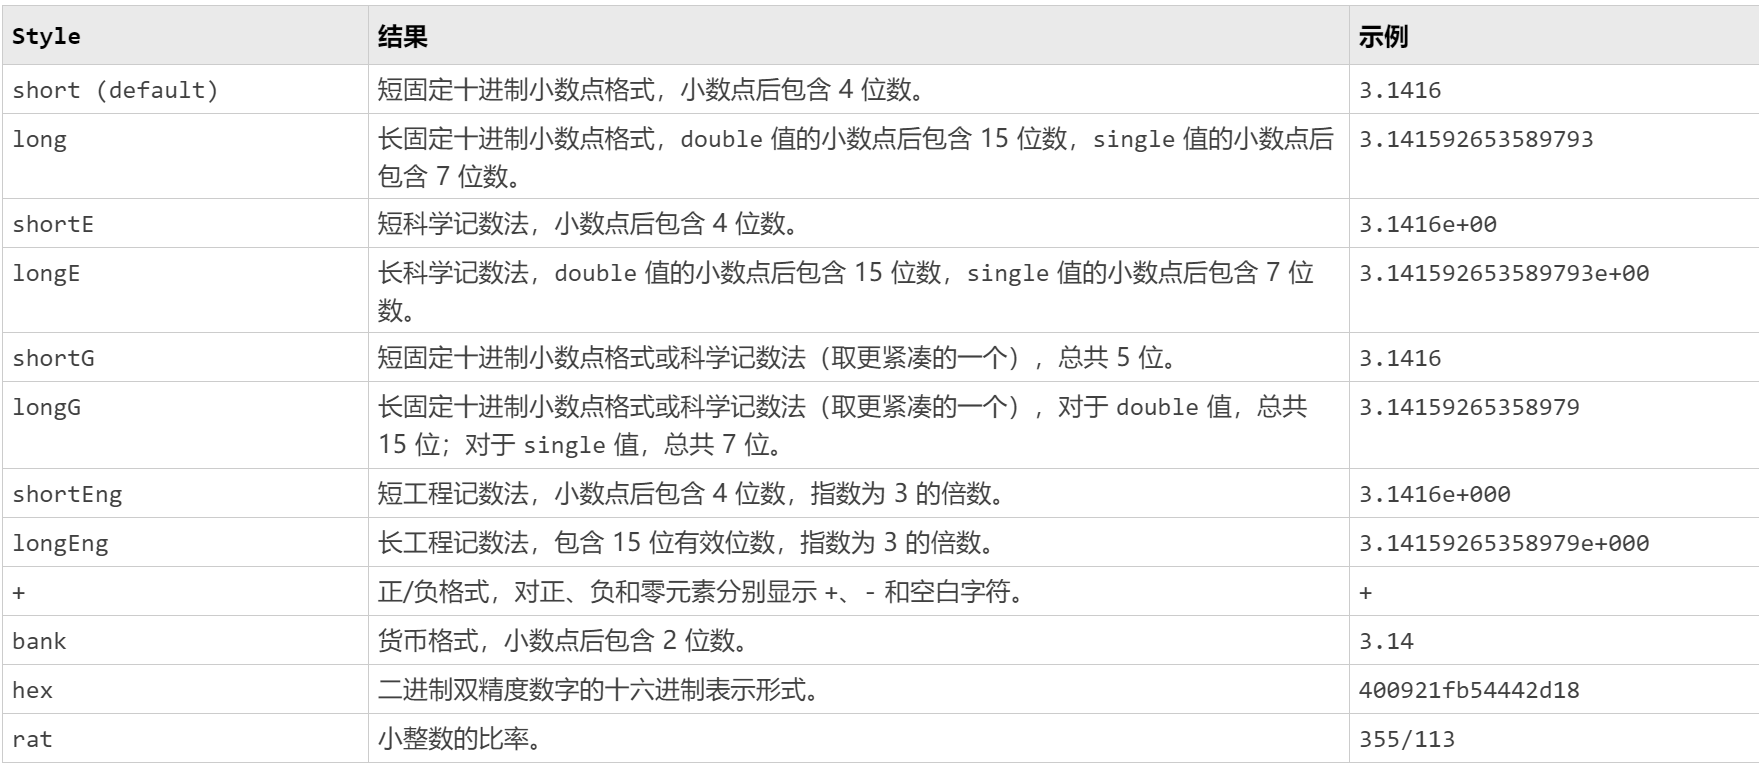

pi

ans =    3.141592653589793


ans

ans =    3.141592653589793


eps

ans =      2.220446049250313e-16


inf

ans =    Inf


NaN

ans =    NaN


c1=10:10:100

c1 =     10    20    30    40    50    60    70    80    90   100


c=sum(c1)

c =    550


d=cumsum(c1)

d =     10    30    60   100   150   210   280   360   450   550


M = movsum(c1,3)

M =     30    60    90   120   150   180   210   240   270   190


E = diff(c1)

E =     10    10    10    10    10    10    10    10    10



A=[1:3:7;2:3:8;3:3:9]

A =      1     4     7
     2     5     8
     3     6     9


B = prod(A)

B =      6   120   504


C = prod(A,2)

C =     28
    80
   162


A = 1:5;
B = cumprod(A)

B =      1     2     6    24   120


A = [1 4 7; 2 5 8; 3 6 9]

A =      1     4     7
     2     5     8
     3     6     9


B = cumprod(A)

B =      1     4     7
     2    20    56
     6   120   504


E = cumprod(A,2)

E =      1     4    28
     2    10    80
     3    18   162


C = 5;
D = magic(3)

D =      8     1     6
     3     5     7
     4     9     2


x = C./D

x =    0.625000000000000   5.000000000000000   0.833333333333333
   1.666666666666667   1.000000000000000   0.714285714285714
   1.250000000000000   0.555555555555556   2.500000000000000



a = 1:2;
b = (1:3)';
a ./ b

ans =    1.000000000000000   2.000000000000000
   0.500000000000000   1.000000000000000
   0.333333333333333   0.666666666666667


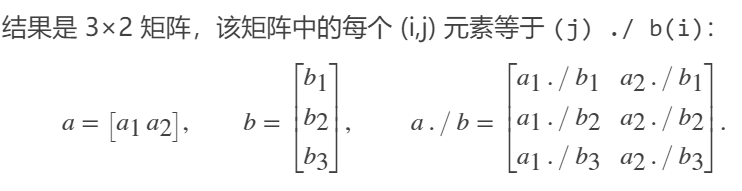

C = 2;
D = [1 2 3; 4 5 6]

D =      1     2     3
     4     5     6


x = D.\C

x =    2.000000000000000   1.000000000000000   0.666666666666667
   0.500000000000000   0.400000000000000   0.333333333333333



a = 1:2

a =      1     2


b = (1:3)'

b =      1
     2
     3


b .\ a

ans =    1.000000000000000   2.000000000000000
   0.500000000000000   1.000000000000000
   0.333333333333333   0.666666666666667


`x =` [`B`](https://ww2.mathworks.cn/help/matlab/ref/ldivide.html#btg5q70-A)`.\`[`A`](https://ww2.mathworks.cn/help/matlab/ref/ldivide.html#btg5q70-A) 用 `A` 的每个元素除以 `B` 的对应元素。`A` 和 `B` 的大小必须相同或[兼容](https://ww2.mathworks.cn/help/matlab/matlab_prog/compatible-array-sizes-for-basic-operations.html)。

如果 `A` 和 `B` 的大小兼容，则这两个数组会隐式扩展以相互匹配。例如，如果 `A` 或 `B` 中有一个是标量，则该标量与另一个数组的每个元素相结合。此外，具有不同方向的向量（一个为行向量，另一个为列向量）会隐式扩展以形成矩阵。

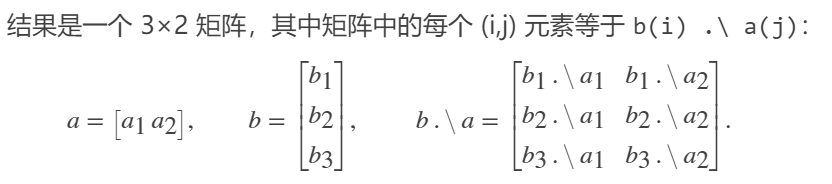

a1=1:2:20;
a2=1:2:20

a2 =      1     3     5     7     9    11    13    15    17    19


% testing
a1(1,3)

ans =      5


b=[1,2,3;4,5,6]

b =      1     2     3
     4     5     6


k1=b(:,1)

k1 =      1
     4


k2=b(2,:)

k2 =      4     5     6


b={1,4;'x',6}

b = 2×2 cell 数组
    {[1]}    {[4]}
    {'x'}    {[6]}


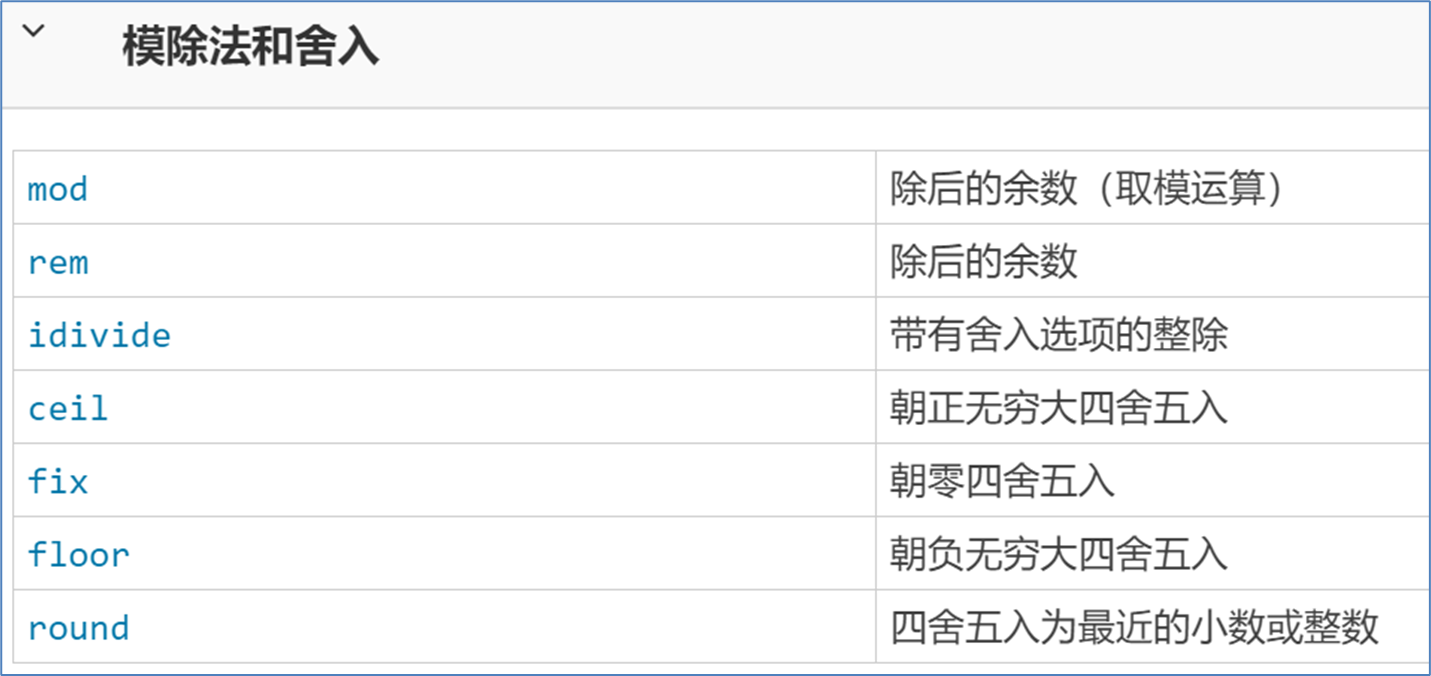

X = [-1.9 -0.2 3.4; 5.6 7 9.2];
Y = ceil(X)

Y =     -1     0     4
     6     7    10



X = [-1.9 -3.4; 1.6 2.5; -4.5 4.5]

X =    -1.9000   -3.4000
    1.6000    2.5000
   -4.5000    4.5000


Y = fix(X)

Y =     -1    -3
     1     2
    -4     4



X = [-1.9  -0.2  3.4;  5.6  7.0  2.4];
Y = floor(X)

Y =     -2    -1     3
     5     7     2


Y = round(X)

Y =     -2     0     3
     6     7     2


rem(10,4) % 余数符号和"被除数"相同

ans = 2

rem(-5,2)

ans = -1

mod(10,4) % 余数符号和"除数"相同

ans = 2

mod(-5,-2)

ans = -1

x=3;
y=4;
z=x^2*y^3/(x-y)^2

z = 576

t=4.1% [s]

t = 4.1000

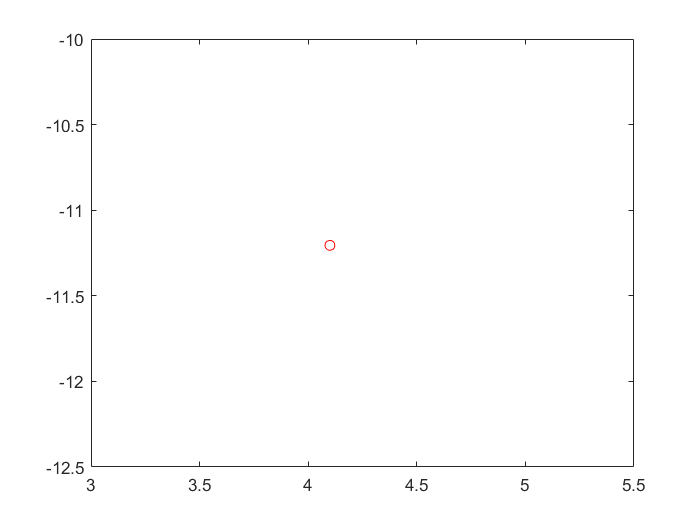

x0=10; % [m]
v0=15; % [m/s]
a=-9.84; % [m/s2]
x=x0+v0*t+0.5*a*t^2;
plot(t,x,'ro')

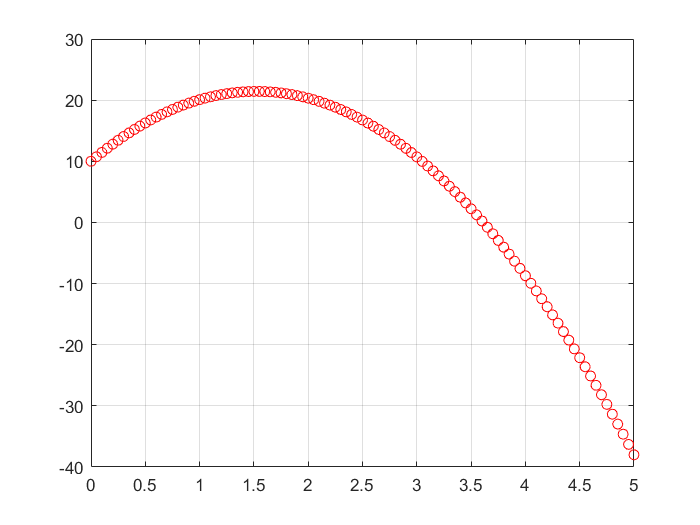

t=0:0.05:5; % [s]
x0=10; % [m]
v0=15; % [m/s]
a=-9.84; % [m/s2]
x=x0+v0.*t+0.5*a.*t.^2;
plot(t,x,'ro')
grid

E=[1 2 3;4 5 6;7 8 9]

E =      1     2     3
     4     5     6
     7     8     9


b=E(2,:)

b =      4     5     6


c=E(:,3);
a=E(:);
f=E([1,3],1);
f1=E(2,[1,3]);
f2=E(3:-1:1,:)

f2 =      7     8     9
     4     5     6
     1     2     3


E(1:2,:)=[]

E =      7     8     9



E=[1 2 3;4 5 6;7 8 9]

E =      1     2     3
     4     5     6
     7     8     9


E1=[1,2,3;4,5,6;7,8,9]

E1 =      1     2     3
     4     5     6
     7     8     9


[E E1]

ans =      1     2     3     1     2     3
     4     5     6     4     5     6
     7     8     9     7     8     9


[E;E1]

ans =      1     2     3
     4     5     6
     7     8     9
     1     2     3
     4     5     6
     7     8     9


E'

ans =      1     4     7
     2     5     8
     3     6     9


K=E([1,3],[1,3])

K =      1     3
     7     9


size(E,1)

ans = 3

%一维数组创建
A1=[0 pi 0.5*pi 0.7 1.5];
A2=0:0.5:3;
A3=linspace(1,6,7);
A4=logspace(1,6,7);

%多维数组的创建
A=[1 2 3 4;linspace(0,5,4);1:2:7;3:6];
B=[1 2 3
    4 5 6
    7 8 9]

B =      1     2     3
     4     5     6
     7     8     9
